# **IDENTIFICACIÓN**

**CARGA DE VALORES WORKSPACE DEL EXPERIMENTO EN LAZO ABIERTO**

%clear all
%clc
load('C:\Users\Atomauro\Desktop\UNIVERSIDAD\CONTROL DIGITAL\ROBOT SCARA\ENTREGA FINAL\MATLAB\CONTROLADORES\Experimento.mat')
s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



opt = stepDataOptions('InputOffset',0,'StepAmplitude',0.2);

%TIEMPO DE MUESTREO
Ts=5*10^-3

Ts = 0.0050

z=tf('z',Ts)


z =
 
  z
 
Sample time: 0.005 seconds
Discrete-time transfer function.



# **MOTOR #1**

**FUNCIÓN DE TRANSFERENCIA CONTINUA Y DISCRETA**

M1v=(2.1447)/(0.33838*s+1)


M1v =
 
     2.145
  ------------
  0.3384 s + 1
 
Continuous-time transfer function.



M1p=feedback((M1v*1/s),1)


M1p =
 
          2.145
  ----------------------
  0.3384 s^2 + s + 2.145
 
Continuous-time transfer function.




stepinfo(M1v)

ans = struct with fields:
        RiseTime: 0.7434
    SettlingTime: 1.3238
     SettlingMin: 1.9399
     SettlingMax: 2.1446
       Overshoot: 0
      Undershoot: 0
            Peak: 2.1446
        PeakTime: 3.5685


stepinfo(M1p)

ans = struct with fields:
        RiseTime: 0.7247
    SettlingTime: 2.3505
     SettlingMin: 0.9106
     SettlingMax: 1.1025
       Overshoot: 10.2483
      Undershoot: 0
            Peak: 1.1025
        PeakTime: 1.5271


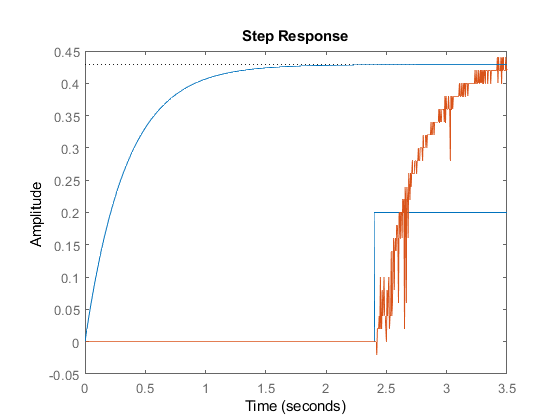


plot(M1A_Ts,M1A_Setpointx100PWM,'DisplayName','M1_Setpointx100PWM');hold on;plot(M1A_Ts,M1A_VelocidadNormalizadarpmrpm,'DisplayName','M1_VelocidadNormalizada Experimental');grid on; title 'EXPERIMENTO STEP 0.2 MOTOR #1'; xlabel 't(s)';ylabel  'Amplitud'; 
hold on
step(M1v,opt)

% step(M1p)
% hold off;
% 
% M1vz=c2d(M1v,Ts)
% M1pz=c2d(M1p,Ts)

M1pz=c2d(M1p, Ts)


# **MOTOR #2**

**FUNCIÓN DE TRANSFERENCIA CONTINUA Y DISCRETA**

M2v=2.45/(0.42*s+1)


M2v =
 
     2.45
  ----------
  0.42 s + 1
 
Continuous-time transfer function.



M2p=feedback(M2v*(1/s),1)


M2p =
 
         2.45
  -------------------
  0.42 s^2 + s + 2.45
 
Continuous-time transfer function.




stepinfo(M2v)

ans = struct with fields:
        RiseTime: 0.9227
    SettlingTime: 1.6431
     SettlingMin: 2.2160
     SettlingMax: 2.4499
       Overshoot: 0
      Undershoot: 0
            Peak: 2.4499
        PeakTime: 4.4293


stepinfo(M2p)

ans = struct with fields:
        RiseTime: 0.6731
    SettlingTime: 3.3692
     SettlingMin: 0.9144
     SettlingMax: 1.1686
       Overshoot: 16.8595
      Undershoot: 0
            Peak: 1.1686
        PeakTime: 1.5087


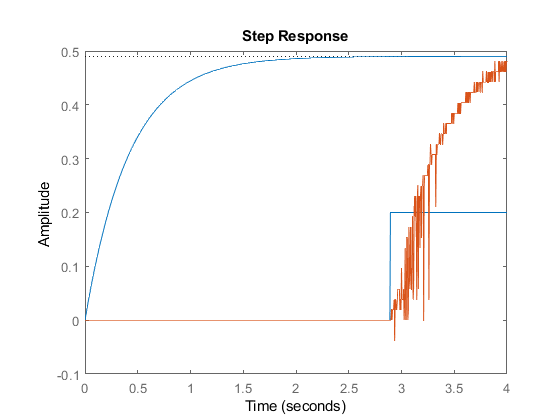


plot(M2A_Ts,M2A_Setpointx100PWM,'DisplayName','M2_Setpointx100PWM');hold on;plot(M2A_Ts,M2A_VelocidadNormalizadarpmrpm,'DisplayName','M2_VelocidadNormalizada Experimental');grid on; title 'EXPERIMENTO STEP 0.2 MOTOR #2'; xlabel 't(s)';ylabel  'Amplitud'; 



step(M2v, opt)

%step(M2p)


M2vz=c2d(M2v,Ts)


M2vz =
 
   0.02899
  ----------
  z - 0.9882
 
Sample time: 0.005 seconds
Discrete-time transfer function.



M2pz=c2d(M2p,Ts)


M2pz =
 
  7.263e-05 z + 7.234e-05
  -----------------------
  z^2 - 1.988 z + 0.9882
 
Sample time: 0.005 seconds
Discrete-time transfer function.



# **CONTROLADORES CONTINUOS **

# **IMPLEMENTACIÓN DIGITAL**

%RESPUESTA ACTUAL MOTOR #1
%tr=0.7247
%tp=1.5271
%Mp=10.2483
%ts(2%)=2.3505
%dcgain=1

%RESPUESTA ACTUAL MOTOR #1
%tr=0.6731
%tp=1.5087
%Mp=16.8595
%ts(2%)=3.3692
%dcgain=1



# **MOTOR #1**

**PID **

%RESPUESTA DESEADA
%essp=0
%TsLC=1.83 (77% TsLA)
%Mp=1.78%


%EULER DE ATRASO
kp = 4.379

kp = 4.3790

ti = 0.8058

ti = 0.8058

td = 0.2015

td = 0.2015


PIDM1s=kp*(1+1/(ti*s)+td*s)


PIDM1s =
 
  0.711 s^2 + 3.529 s + 4.379
  ---------------------------
           0.8058 s
 
Continuous-time transfer function.




%PIDM1z=kp*(1+(1/ti)*(Ts*z/(z-1))+(td*(z-1)/(Ts*z)))

%PIDM1z=(118.7*z^2-234*z+115.3)/(z^2-z)
PIDM1z=(118.7*z^2-250*z+115.3)/(z^2-z)


PIDM1z =
 
  118.7 z^2 - 250 z + 115.3
  -------------------------
           z^2 - z
 
Sample time: 0.005 seconds
Discrete-time transfer function.



LCM1 = zpk(feedback(PIDM1z*M1pz,1))    


LCM1 =
 
   0.0093579 (z+0.9951) (z-1.424) (z-0.6821)
  --------------------------------------------
  (z-1.127) (z-0.00934) (z^2 - 1.839z + 0.859)
 
Sample time: 0.005 seconds
Discrete-time zero/pole/gain model.




M1LCs=feedback(PIDM1s*M1p,1)


M1LCs =
 
        1.525 s^2 + 7.568 s + 9.392
  ----------------------------------------
  0.2727 s^3 + 2.331 s^2 + 9.296 s + 9.392
 
Continuous-time transfer function.



M1LCz=feedback(PIDM1z*M1pz,1)


M1LCz =
 
  0.009358 z^3 - 0.0104 z^2 - 0.01052 z + 0.009045
  ------------------------------------------------
  z^4 - 2.976 z^3 + 2.96 z^2 - 0.9959 z + 0.009045
 
Sample time: 0.005 seconds
Discrete-time transfer function.



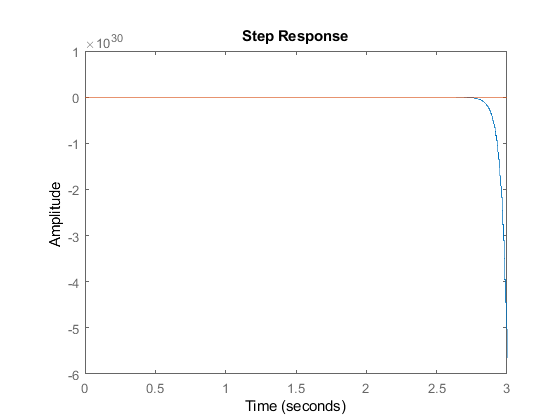

step(M1LCz,M1LCs)


Esfuerzo=feedback(PIDM1z,1)


Esfuerzo =
 
  118.7 z^2 - 250 z + 115.3
  -------------------------
  119.7 z^2 - 251 z + 115.3
 
Sample time: 0.005 seconds
Discrete-time transfer function.



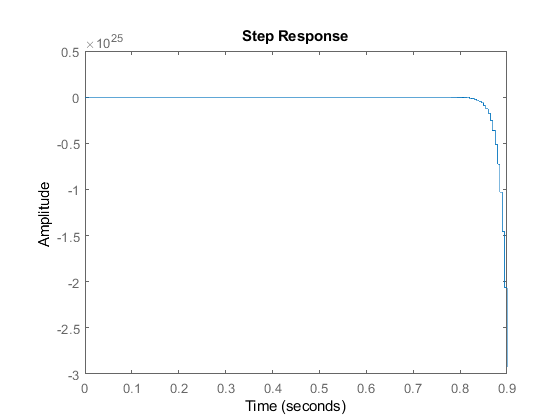

step(Esfuerzo)

**PI-D DISCRETO **

%RESPUESTA DESEADA
%essp=0
%TsLC=1.4 (50% TsLA)
%Mp=0%

%EULER DE ATRASO
kp = 2.938

kp = 2.9380

ti = 1.214

ti = 1.2140

td = 0.3035

td = 0.3035

b=1;
c=0;
%PI_DM2s=kp*(1+1/(ti*s))-td*s
%PI_DM2z=kp*(1+(1/ti)*(Ts*z/(z-1)))-(td*(z-1)/(Ts*z))
p1s=feedback(M2v,td)


p1s =
 
       2.45
  --------------
  0.42 s + 1.744
 
Continuous-time transfer function.



p2s=kp*(1+1/(ti*s))


p2s =
 
  3.567 s + 2.938
  ---------------
      1.214 s
 
Continuous-time transfer function.



M2LCs=feedback(p2s*p1s,1)


M2LCs =
 
        8.738 s + 7.198
  ----------------------------
  0.5099 s^2 + 10.86 s + 7.198
 
Continuous-time transfer function.




p1z=feedback(M2vz,td)


p1z =
 
   0.02899
  ----------
  z - 0.9794
 
Sample time: 0.005 seconds
Discrete-time transfer function.



p2z=kp*(1+(1/ti)*(Ts*z/(z-1)))


p2z =
 
  2.95 z - 2.938
  --------------
      z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.



M2LCz=feedback(p2z*p1z,1)


M2LCz =
 
   0.08553 z - 0.08518
  ----------------------
  z^2 - 1.894 z + 0.8942
 
Sample time: 0.005 seconds
Discrete-time transfer function.




stepinfo(M2LCz)

ans = struct with fields:
        RiseTime: 0.7950
    SettlingTime: 3.1600
     SettlingMin: 0.9001
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 7.9950


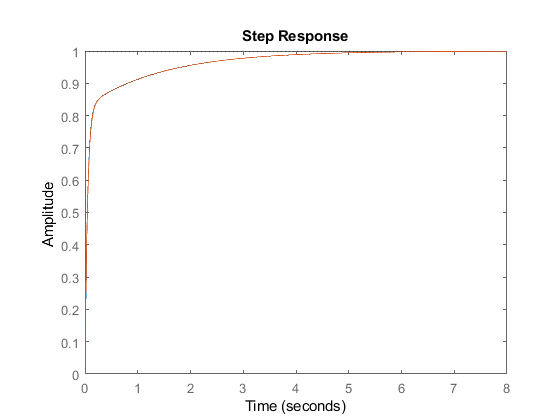


%zpk(PI_DM2z*M2pz)
step(M2LCz,M2LCs)  

# **MOTOR #2**

**PID**

%RESPUESTA DESEADA
%essp=0
%TsLC=2.33 (69% TsLA)
%Mp=0.756%

%EULER DE ATRASO
kp = 2.964

kp = 2.9640

ti = 0.8448

ti = 0.8448

td = 0.2112

td = 0.2112

PIDM2s=kp*(1+1/(ti*s)+td*s)


PIDM2s =
 
  0.5288 s^2 + 2.504 s + 2.964
  ----------------------------
            0.8448 s
 
Continuous-time transfer function.



PIDM2z=kp*(1+(1/ti)*(Ts*z/(z-1))+(td*(z-1)/(Ts*z)))


PIDM2z =
 
  0.6409 z^2 - 1.267 z + 0.626
  ----------------------------
      0.005 z^2 - 0.005 z
 
Sample time: 0.005 seconds
Discrete-time transfer function.




%EULER DE ADELANTO
% kp = 3.06
% ti = 0.8279
% td = 0.207
% PIDM2s=kp*(1+1/(ti*s)+td*s)
% PIDM2z=kp*(1+(1/ti)*(Ts/(z-1))+(td*(z-1)/Ts))

LCM2 = zpk(feedback(PIDM2z*M2pz,1))


LCM2 =
 
         0.0093094 (z+0.996) (z-0.9883)^2
  -----------------------------------------------
  (z-0.9942) (z-0.009337) (z^2 - 1.975z + 0.9757)
 
Sample time: 0.005 seconds
Discrete-time zero/pole/gain model.




M2LCs=feedback(PIDM2s*M2p,1)


M2LCs =
 
        1.296 s^2 + 6.135 s + 7.262
  ---------------------------------------
  0.3548 s^3 + 2.14 s^2 + 8.205 s + 7.262
 
Continuous-time transfer function.



M2LCz=feedback(PIDM2z*M2pz,1)


M2LCz =
 
     4.655e-05 z^3 - 4.564e-05 z^2 - 4.618e-05 z + 4.528e-05
  --------------------------------------------------------------
  0.005 z^4 - 0.01489 z^3 + 0.01484 z^2 - 0.004987 z + 4.528e-05
 
Sample time: 0.005 seconds
Discrete-time transfer function.



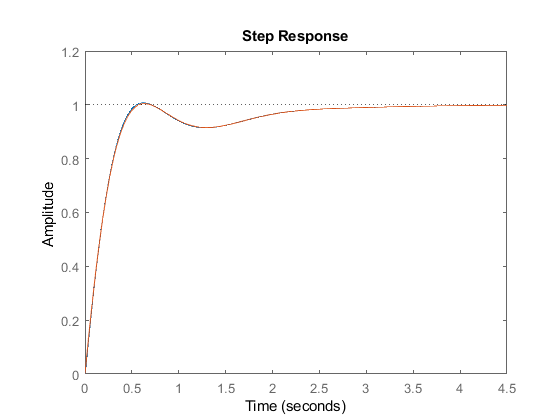

step(M2LCz,M2LCs)


Esfuerzo=feedback(PIDM2z,1)


Esfuerzo =
 
  0.6409 z^2 - 1.267 z + 0.626
  ----------------------------
  0.6459 z^2 - 1.272 z + 0.626
 
Sample time: 0.005 seconds
Discrete-time transfer function.



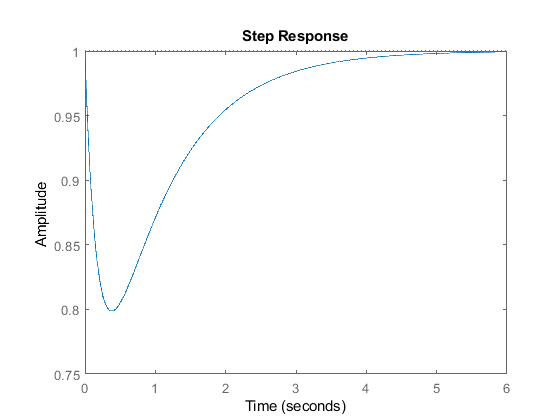

step(Esfuerzo)

**PI-D DISCRETO **

%RESPUESTA DESEADA
%essp=0
%TsLC=1.4 (50% TsLA)
%Mp=0%

%EULER DE ATRASO
kp = 2.938

kp = 2.9380

ti = 1.214

ti = 1.2140

td = 0.3035

td = 0.3035

b=1;
c=0;
%PI_DM2s=kp*(1+1/(ti*s))-td*s
%PI_DM2z=kp*(1+(1/ti)*(Ts*z/(z-1)))-(td*(z-1)/(Ts*z))
p1s=feedback(M2v,td)


p1s =
 
       2.45
  --------------
  0.42 s + 1.744
 
Continuous-time transfer function.



p2s=kp*(1+1/(ti*s))


p2s =
 
  3.567 s + 2.938
  ---------------
      1.214 s
 
Continuous-time transfer function.



M2LCs=feedback(p2s*p1s,1)


M2LCs =
 
        8.738 s + 7.198
  ----------------------------
  0.5099 s^2 + 10.86 s + 7.198
 
Continuous-time transfer function.




p1z=feedback(M2vz,td)


p1z =
 
   0.02899
  ----------
  z - 0.9794
 
Sample time: 0.005 seconds
Discrete-time transfer function.



p2z=kp*(1+(1/ti)*(Ts*z/(z-1)))


p2z =
 
  2.95 z - 2.938
  --------------
      z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.



M2LCz=feedback(p2z*p1z,1)


M2LCz =
 
   0.08553 z - 0.08518
  ----------------------
  z^2 - 1.894 z + 0.8942
 
Sample time: 0.005 seconds
Discrete-time transfer function.




stepinfo(M2LCz)

ans = struct with fields:
        RiseTime: 0.7950
    SettlingTime: 3.1600
     SettlingMin: 0.9001
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 7.9950



%zpk(PI_DM2z*M2pz)
step(M2LCz,M2LCs)   

# **CONTROLADORES DIGITAL **

# **IMPLEMENTACIÓN DIGITAL**

# **MOTOR #1**

**RST (REFERENCE SIGNAL TRACKING) ~ POSICIONAL**

clc
clear all
close all

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



Mv=(2.1447)/(0.33838*s+1)


Mv =
 
     2.145
  ------------
  0.3384 s + 1
 
Continuous-time transfer function.



Mp=feedback((Mv*1/s),1)


Mp =
 
          2.145
  ----------------------
  0.3384 s^2 + s + 2.145
 
Continuous-time transfer function.




si=stepinfo(Mp,'SettlingTimeThreshold',0.01)

si = struct with fields:
        RiseTime: 0.7247
    SettlingTime: 3.2154
     SettlingMin: 0.9106
     SettlingMax: 1.1025
       Overshoot: 10.2483
      Undershoot: 0
            Peak: 1.1025
        PeakTime: 1.5271


tsLA=si.SettlingTime

tsLA = 3.2154


nit = 400; umin = 0; umax = 4.9; 
u(1:10) = 0; erro(1:10) = 0; y(1:10) = 0;
% Referência
r(1:100) = 1; r(101:200) = 4; r(201:300) = 2; r(301:nit) = 3;
%% Planta
T=5*10^-3;                          %Tempo de muestreo
s=tf('s');
z=tf('z',T);

ftz=c2d(Mp,T);                  %Planta Discreta
[B,A]=tfdata(ftz,'v');          %Divide Numerador em B e denominador em A
 
gpz=filt(B,A,T,'name','Planta')      %Funcao de transferenca discreta


gpz =
 
  7.884e-05 z^-1 + 7.845e-05 z^-2
  -------------------------------
   1 - 1.985 z^-1 + 0.9853 z^-2
 
Name: Planta
Sample time: 0.005 seconds
Discrete-time transfer function.



 
%% PMF
%Asignacion de Polos
Ts=0.5*tsLA;                      %Tempo de estabelecimento deseado lazo cerrado
ep=0.71;                     %Epsilon (Coeficiente de amortiguamiento)
wn=4/(ep*Ts);               %Frecuencia natural del sistema
 
%Polos conjugados
p1=-2*exp(-ep*wn*T)*cos(wn*T*sqrt(1-ep^2))

p1 = -1.9751

p2=exp(-2*ep*wn*T)

p2 = 0.9754

 
% Polinomio deseado con un polo en el origen
Am=[1 p1 p2 0];
 
%Resolução de Equações metodo matricial
M=[1 0 B(2); A(2) B(2) B(3); A(3) B(3) 0];
q=[Am(2)-A(2); Am(3)-A(3);Am(4)];
X=inv(M)*q;
 
R=[1 X(1)]             %Polinomio R

R =     1.0000    0.0050


S=[X(3) X(2)]            %Polinomio S

S =    63.9003  -62.9775


%Polinomio T
Tz=sum(Am)/sum(B)

Tz = 1.9277

 
Rz=tf(1,R,T)


Rz =
 
       1
  ------------
  z + 0.005014
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Sz=X(3)*z + X(2)


Sz =
 
  63.9 z - 62.98
 
Sample time: 0.005 seconds
Discrete-time transfer function.




LC=feedback(Rz*gpz,Sz)*Tz


LC =
 
         0.000152 z^-2 + 0.0001512 z^-3
  ---------------------------------------------
  1 - 1.975 z^-1 + 0.9754 z^-2 + 1.735e-18 z^-3
 
Sample time: 0.005 seconds
Discrete-time transfer function.



step(LC,gpz)


for k = 4:nit
   
    y(k)=B(2)*u(k-1)+B(3)*u(k-2)-A(2)*y(k-1)-A(3)*y(k-2);
    u(k)=Tz*r(k)-S(1)*y(k)-S(2)*y(k-1)+R(2)*u(k-1);
    %     Saturação
    if u(k) >= umax 
     u(k) = umax;
     elseif u(k) <= umin
     u(k) = umin;
    end
end
 
t = 0:T:(nit-1)*T;
 
figure
subplot(2,1,1),plot(t,r,'--k',t,y,'-r','Linewidth',2.5)
xlabel('Tempo (s)');
ylabel('Velocidade');
legend('y_r','y','Location','SouthEast')
grid on;
hold

Current plot held


subplot(2,1,2),plot(t,u,'--b','Linewidth',3)
xlabel('Tempo (s)');
ylabel('Controle (volts)');
legend('u')
grid on;

**RST (REFERENCE SIGNAL TRACKING) ~ INCREMENTAL**

clear all
close all

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



Mv=(2.1447)/(0.33838*s+1)


Mv =
 
     2.145
  ------------
  0.3384 s + 1
 
Continuous-time transfer function.



Mp=feedback((Mv*1/s),1)


Mp =
 
          2.145
  ----------------------
  0.3384 s^2 + s + 2.145
 
Continuous-time transfer function.



si=stepinfo(Mp,'SettlingTimeThreshold',0.01)

si = struct with fields:
        RiseTime: 0.7247
    SettlingTime: 3.2154
     SettlingMin: 0.9106
     SettlingMax: 1.1025
       Overshoot: 10.2483
      Undershoot: 0
            Peak: 1.1025
        PeakTime: 1.5271


tsLA=si.SettlingTime

tsLA = 3.2154


%Condiciones iniciales
nit = 400; umin = 0; umax = 4.9; ts = 0.1;
u(1:10) = 0; erro(1:10) = 0; y(1:10) = 0;
% Referência
r(1:100) = 1; r(101:200) = 4; r(201:300) = 3; r(301:nit) = 3;

T=5*10^-3

T = 0.0050

z=tf('z',T)


z =
 
  z
 
Sample time: 0.005 seconds
Discrete-time transfer function.




%% Planta
ftz=c2d(Mp,T);                  %Planta Discreta
[B,A]=tfdata(ftz,'v');          %Divide Numerador em B e denominador em A
nb=length(B);                   %Ordem do numerador
na=length(A)-1;                 %Ordem do Denominador
nr=nb-1;                        %Ordem do polinomio R
ns=na;                        %Ordem do Polinomio S
 
gpz=filt(B,A,T,'name','Planta');      %Funcao de transferenca discreta
 
%% PMF
%Asignacion de Polos
Ts=0.5*tsLA;                      %Tempo de estabelecimento deseado lazo cerrado
ep=0.8;                     %Epsilon (Coeficiente de amortiguamiento)
wn=4/(ep*Ts);               %Frecuencia natural del sistema
 
%Polos conjugados
za=exp(-ep*wn*T);
th=57.3*wn*T*sqrt(1-ep^2);
polos=za*[cosd(th)+i*sind(th),cosd(th)-i*sind(th)];
 
% Polinomio deseado
Am=poly([polos 0 0]);
 
%Delata A. Multiplica por integrador
DA=conv(A,[1 -1]);
 
%Resolução de Equações metodo matricial
M=[1 B(2) 0 0; DA(2) B(3) B(2) 0; DA(3) 0 B(3) B(2);DA(4) 0 0 B(3)];
q=[Am(2)-DA(2); Am(3)-DA(3);Am(4)-DA(4);Am(5)];
X=inv(M)*q;
 
R=[1 X(1)]             %Polinomio R

R =     1.0000    0.5013


S=X(2:end)'            %Polinomio S

S = 	1.0e+04 *

    0.6453   -1.2747    0.6296


 
%Polinomio T
Tz=sum(S)

Tz = 1.5185

 
Rz=tf(1,R,T)


Rz =
 
      1
  ----------
  z + 0.5013
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Sz=tf(S,1,T)


Sz =
 
  6453 z^2 - 1.275e04 z + 6296
 
Sample time: 0.005 seconds
Discrete-time transfer function.




LC=feedback(Rz*gpz,Sz)*Tz


LC =
 
         0.0001197 z^-2 + 0.0001191 z^-3
  ----------------------------------------------
  1.509 - 1.983 z^-1 - 0.5134 z^-2 + 0.9878 z^-3
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Kadicional=dcgain(LC)

Kadicional = 0.5029

LC=LC*1/Kadicional


LC =
 
          0.0001197 z^-2 + 0.0001191 z^-3
  -----------------------------------------------
  0.7587 - 0.997 z^-1 - 0.2582 z^-2 + 0.4967 z^-3
 
Sample time: 0.005 seconds
Discrete-time transfer function.



step(LC,gpz)

%Ingresa la perturbacion en el instante 300
% d0(1:300)=0;
% d0(301:nit)=0.05;
%  
% for k = 5:nit
%     %Salida de la Planta
%     y(k)=B(2)*u(k-1)+B(3)*u(k-2)-A(2)*y(k-1)-A(3)*y(k-2)+d0(k);
%     %Ley de Control
%     u(k)=Tz*r(k)-S(1)*y(k)-S(2)*y(k-1)-S(3)*y(k-2)-(R(2)-1)*u(k-1)+R(2)*u(k-2);
%     %     Saturação
%     if u(k) >= umax 
%      u(k) = umax;
%      elseif u(k) <= umin
%      u(k) = umin;
%     end
% end
%  
% t = 0:ts:(nit-1)*ts;
%  
% figure
% subplot(2,1,1),plot(t,r,'--k',t,y,'-r','Linewidth',2.5)
% xlabel('Tempo (s)');
% ylabel('Velocidade');
% legend('y_r','y','Location','SouthEast')
% grid on;
% hold
% subplot(2,1,2),plot(t,u,'--b','Linewidth',3)
% xlabel('Tempo (s)');
% ylabel('Controle (volts)');
% legend('u')
% grid on;

# **MOTOR #2**

**RST (REFERENCE SIGNAL TRACKING) ~ POSICIONAL**

clc
clear all
close all

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



Mv=2.45/(0.42*s+1)


Mv =
 
     2.45
  ----------
  0.42 s + 1
 
Continuous-time transfer function.



Mp=feedback(Mv*(1/s),1)


Mp =
 
         2.45
  -------------------
  0.42 s^2 + s + 2.45
 
Continuous-time transfer function.



si=stepinfo(Mp,'SettlingTimeThreshold',0.01)

si = struct with fields:
        RiseTime: 0.6731
    SettlingTime: 3.6386
     SettlingMin: 0.9144
     SettlingMax: 1.1686
       Overshoot: 16.8595
      Undershoot: 0
            Peak: 1.1686
        PeakTime: 1.5087


tsLA=si.SettlingTime

tsLA = 3.6386


nit = 400; umin = 0; umax = 4.9; 
u(1:10) = 0; erro(1:10) = 0; y(1:10) = 0;
% Referência
r(1:100) = 1; r(101:200) = 4; r(201:300) = 2; r(301:nit) = 3;
%% Planta
T=5*10^-3;                          %Tempo de muestreo
s=tf('s');
z=tf('z',T);

ftz=c2d(Mp,T);                  %Planta Discreta
[B,A]=tfdata(ftz,'v');          %Divide Numerador em B e denominador em A
 
gpz=filt(B,A,T,'name','Planta')      %Funcao de transferenca discreta


gpz =
 
  7.263e-05 z^-1 + 7.234e-05 z^-2
  -------------------------------
   1 - 1.988 z^-1 + 0.9882 z^-2
 
Name: Planta
Sample time: 0.005 seconds
Discrete-time transfer function.



 
%% PMF
%Asignacion de Polos
Ts=0.5*tsLA;                      %Tempo de estabelecimento deseado lazo cerrado
ep=0.71;                     %Epsilon (Coeficiente de amortiguamiento)
wn=4/(ep*Ts);               %Frecuencia natural del sistema
 
%Polos conjugados
p1=-2*exp(-ep*wn*T)*cos(wn*T*sqrt(1-ep^2))

p1 = -1.9780

p2=exp(-2*ep*wn*T)

p2 = 0.9783

 
% Polinomio deseado con un polo en el origen
Am=[1 p1 p2 0];
 
%Resolução de Equações metodo matricial
M=[1 0 B(2); A(2) B(2) B(3); A(3) B(3) 0];
q=[Am(2)-A(2); Am(3)-A(3);Am(4)];
X=inv(M)*q;
 
R=[1 X(1)]             %Polinomio R

R =     1.0000    0.0050


S=[X(3) X(2)]            %Polinomio S

S =    68.9210  -68.2903


%Polinomio T
Tz=sum(Am)/sum(B)

Tz = 1.6357

 
Rz=tf(1,R,T)


Rz =
 
       1
  ------------
  z + 0.004999
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Sz=X(3)*z + X(2)


Sz =
 
  68.92 z - 68.29
 
Sample time: 0.005 seconds
Discrete-time transfer function.




LC=feedback(Rz*gpz,Sz)*Tz


LC =
 
  0.0001188 z^-2 + 0.0001183 z^-3
  -------------------------------
   1 - 1.978 z^-1 + 0.9783 z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.



step(LC,gpz)


for k = 4:nit
   
    y(k)=B(2)*u(k-1)+B(3)*u(k-2)-A(2)*y(k-1)-A(3)*y(k-2);
    u(k)=Tz*r(k)-S(1)*y(k)-S(2)*y(k-1)+R(2)*u(k-1);
    %     Saturação
    if u(k) >= umax 
     u(k) = umax;
     elseif u(k) <= umin
     u(k) = umin;
    end
end
 
t = 0:T:(nit-1)*T;
 
figure
subplot(2,1,1),plot(t,r,'--k',t,y,'-r','Linewidth',2.5)
xlabel('Tempo (s)');
ylabel('Velocidade');
legend('y_r','y','Location','SouthEast')
grid on;
hold

Current plot held


subplot(2,1,2),plot(t,u,'--b','Linewidth',3)
xlabel('Tempo (s)');
ylabel('Controle (volts)');
legend('u')
grid on;

**RST (REFERENCE SIGNAL TRACKING) ~ INCREMENTAL**

clear all
close all

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



Mv=2.45/(0.42*s+1)


Mv =
 
     2.45
  ----------
  0.42 s + 1
 
Continuous-time transfer function.



Mp=feedback(Mv*(1/s),1)


Mp =
 
         2.45
  -------------------
  0.42 s^2 + s + 2.45
 
Continuous-time transfer function.



si=stepinfo(Mp,'SettlingTimeThreshold',0.01)

si = struct with fields:
        RiseTime: 0.6731
    SettlingTime: 3.6386
     SettlingMin: 0.9144
     SettlingMax: 1.1686
       Overshoot: 16.8595
      Undershoot: 0
            Peak: 1.1686
        PeakTime: 1.5087


tsLA=si.SettlingTime

tsLA = 3.6386


%Condiciones iniciales
nit = 400; umin = 0; umax = 4.9; ts = 0.1;
u(1:10) = 0; erro(1:10) = 0; y(1:10) = 0;
% Referência
r(1:100) = 1; r(101:200) = 4; r(201:300) = 3; r(301:nit) = 3;

T=5*10^-3

T = 0.0050

z=tf('z',T)


z =
 
  z
 
Sample time: 0.005 seconds
Discrete-time transfer function.




%% Planta
ftz=c2d(Mp,T);                  %Planta Discreta
[B,A]=tfdata(ftz,'v');          %Divide Numerador em B e denominador em A
nb=length(B);                   %Ordem do numerador
na=length(A)-1;                 %Ordem do Denominador
nr=nb-1;                        %Ordem do polinomio R
ns=na;                        %Ordem do Polinomio S
 
gpz=filt(B,A,T,'name','Planta');      %Funcao de transferenca discreta
 
%% PMF
%Asignacion de Polos
Ts=0.5*tsLA;                      %Tempo de estabelecimento deseado lazo cerrado
ep=0.8;                     %Epsilon (Coeficiente de amortiguamiento)
wn=4/(ep*Ts);               %Frecuencia natural del sistema
 
%Polos conjugados
za=exp(-ep*wn*T);
th=57.3*wn*T*sqrt(1-ep^2);
polos=za*[cosd(th)+i*sind(th),cosd(th)-i*sind(th)];
 
% Polinomio deseado
Am=poly([polos 0 0]);
 
%Delata A. Multiplica por integrador
DA=conv(A,[1 -1]);
 
%Resolução de Equações metodo matricial
M=[1 B(2) 0 0; DA(2) B(3) B(2) 0; DA(3) 0 B(3) B(2);DA(4) 0 0 B(3)];
q=[Am(2)-DA(2); Am(3)-DA(3);Am(4)-DA(4);Am(5)];
X=inv(M)*q;
 
R=[1 X(1)]             %Polinomio R

R =     1.0000    0.5015


S=X(2:end)'            %Polinomio S

S = 	1.0e+04 *

    0.7001   -1.3850    0.6850


 
%Polinomio T
Tz=sum(S)

Tz = 1.2884

 
Rz=tf(1,R,T)


Rz =
 
      1
  ----------
  z + 0.5015
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Sz=tf(S,1,T)


Sz =
 
  7001 z^2 - 1.385e04 z + 6850
 
Sample time: 0.005 seconds
Discrete-time transfer function.




LC=feedback(Rz*gpz,Sz)*Tz


LC =
 
         9.358e-05 z^-2 + 9.321e-05 z^-3
  ----------------------------------------------
  1.508 - 1.986 z^-1 - 0.5132 z^-2 + 0.9911 z^-3
 
Sample time: 0.005 seconds
Discrete-time transfer function.



Kadicional=dcgain(LC)

Kadicional = 0.4618

LC=LC*1/Kadicional


LC =
 
          9.358e-05 z^-2 + 9.321e-05 z^-3
  -----------------------------------------------
  0.6966 - 0.9172 z^-1 - 0.237 z^-2 + 0.4577 z^-3
 
Sample time: 0.005 seconds
Discrete-time transfer function.



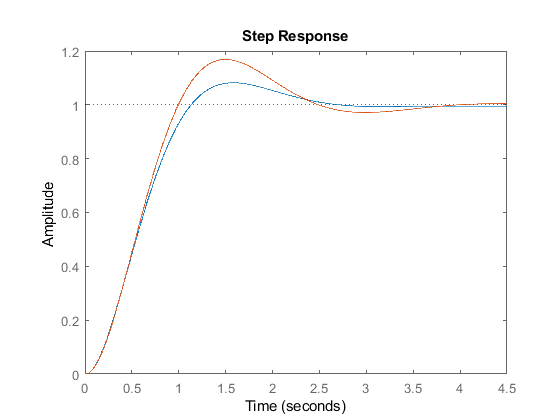

step(LC,gpz)


%Ingresa la perturbacion en el instante 300
% d0(1:300)=0;
% d0(301:nit)=0.05;
%  
% for k = 5:nit
%     %Salida de la Planta
%     y(k)=B(2)*u(k-1)+B(3)*u(k-2)-A(2)*y(k-1)-A(3)*y(k-2)+d0(k);
%     %Ley de Control
%     u(k)=Tz*r(k)-S(1)*y(k)-S(2)*y(k-1)-S(3)*y(k-2)-(R(2)-1)*u(k-1)+R(2)*u(k-2);
%     %     Saturação
%     if u(k) >= umax 
%      u(k) = umax;
%      elseif u(k) <= umin
%      u(k) = umin;
%     end
% end
%  
% t = 0:ts:(nit-1)*ts;
%  
% figure
% subplot(2,1,1),plot(t,r,'--k',t,y,'-r','Linewidth',2.5)
% xlabel('Tempo (s)');
% ylabel('Velocidade');
% legend('y_r','y','Location','SouthEast')
% grid on;
% hold
% subplot(2,1,2),plot(t,u,'--b','Linewidth',3)
% xlabel('Tempo (s)');
% ylabel('Controle (volts)');
% legend('u')
% grid on;